## An implementation of multistage MPC for the plasma thermal effect/dose delivery problem

created with influences from code by Angelo D. Bonzanini and Joel A. Paulson

(c) Kimberly Chan, Mesbah Lab 2022

close all; clear; clc;

## add package paths

when running this Live Script, make sure you are in the main project directory (not in the directory of this script)!!

addpath(genpath('./config'), genpath('./utils'))    % add modular package functions to path
casadipath = [];%'~/casadi-linux-matlab-v3.5.5';        % add casadi to path (leave empty if already done)
if ~isempty(casadipath)
    addpath(casadipath)
end

## user inputs

economic_flag = true;   % economic objective flag (CEM setpoint tracking for plasma case studies)
robust_flag = true;     % robust MPC implementation flag (multistage MPC)
offset_flag = false;    % offset-free MPC (reference tracking)
save_file = [];     % filename to save data for future use; leave empty if no save is desired
font_size = 15;     % font size for plotting
line_width = 3;     % line width for plotting

## load problem data

prob_info = multistage_load_problem_info();

Linear Model to be used for CONTROL:
A: 
    0.9027    0.0175
    0.1316    0.2426

B: 
    0.5815   -0.2204
    2.6737   -1.1310

C: 
     1     0
     0     1

xss: 
   33.3060
    7.7358

Linear Model to be used for the PLANT:
A: 
    0.8875    0.0546
    0.0935    0.2827

B: 
    0.5028   -0.1740
    2.7637   -1.0366

C: 
     1     0
     0     1

xss: 
   33.3060    7.7358



## set up controller

c = MultistageMPC(prob_info);
c = c.get_mpc();
[c, res, feas] = c.solve_mpc(); % do test run

## initialize simulation

Nsim = 240; % simulation horizon
sim = Simulation(Nsim, prob_info);
% run simulation
[sim, sim_data] = sim.run_closed_loop(c, [], [], economic_flag, robust_flag, offset_flag);

Using a MPC.
Using user-provided plant...


disp('sim_data fields:'); disp(fieldnames(sim_data))

sim_data fields:
    {'Xsim'   }
    {'Ysim'   }
    {'Usim'   }
    {'Jsim'   }
    {'Yrefsim'}
    {'ctime'  }
    {'Xhat'   }
    {'Ypred'  }
    {'CEMsim' }



sim_ref = sim_data.Yrefsim;
CEMsim = sim_data.CEMsim(:,1:end-1);
mask = CEMsim < sim_ref;
ctime = sim_data.ctime(mask);
fprintf('Total Runtime: %.4f s\n', sum(ctime))

Total Runtime: 7.1243 s


fprintf('Average Runtime: %.4f s\n', mean(ctime))

Average Runtime: 0.0589 s


## plot data

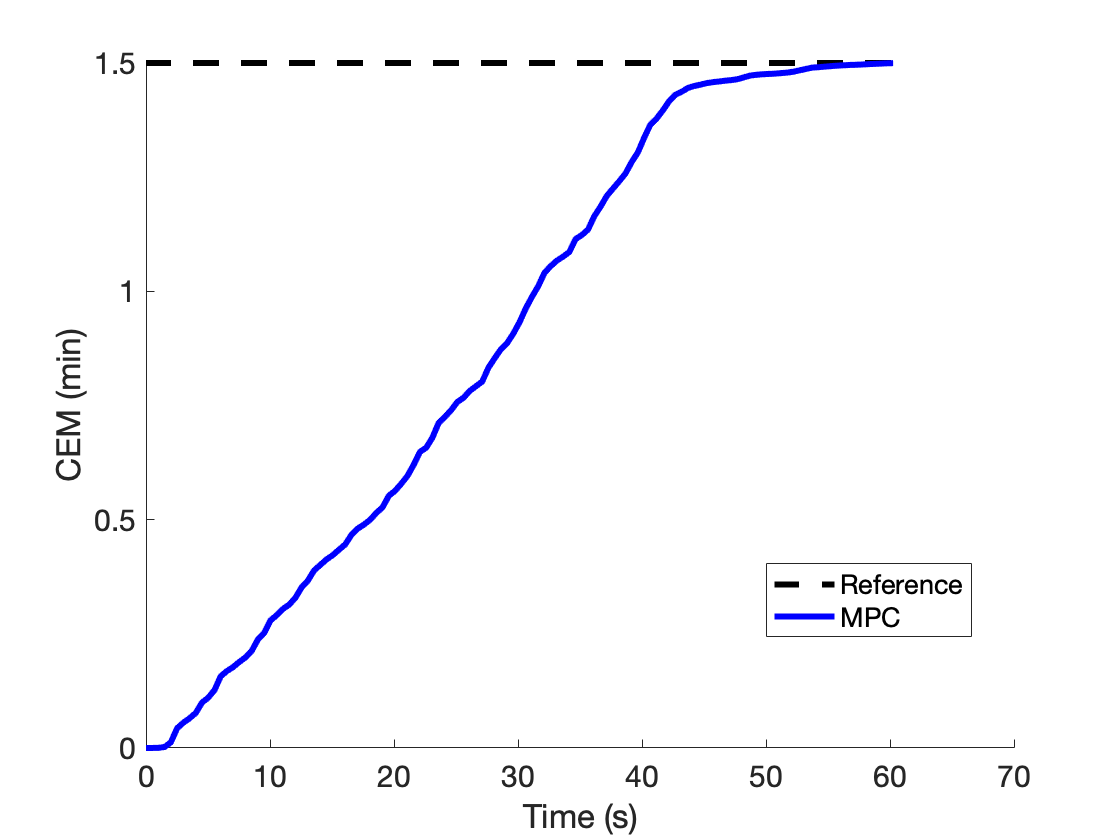

CEMplot = CEMsim(mask);
ref_plot = sim_ref(mask);
Tplot = sim_data.Xhat(1,1:end-1) + prob_info.xssp(1);
Tplot = Tplot(mask);

t = linspace(0,Nsim,Nsim)*prob_info.ts;

figure()
subplot(111)
hold on
plot(t(mask), ref_plot, 'k--', 'LineWidth', line_width, 'DisplayName', 'Reference')
plot(t(mask), CEMplot, 'b-', 'LineWidth', line_width, 'DisplayName', 'MPC')
xlabel('Time (s)')
ylabel('CEM (min)')
legend('location', 'best')
set(gca, 'Fontsize', font_size)

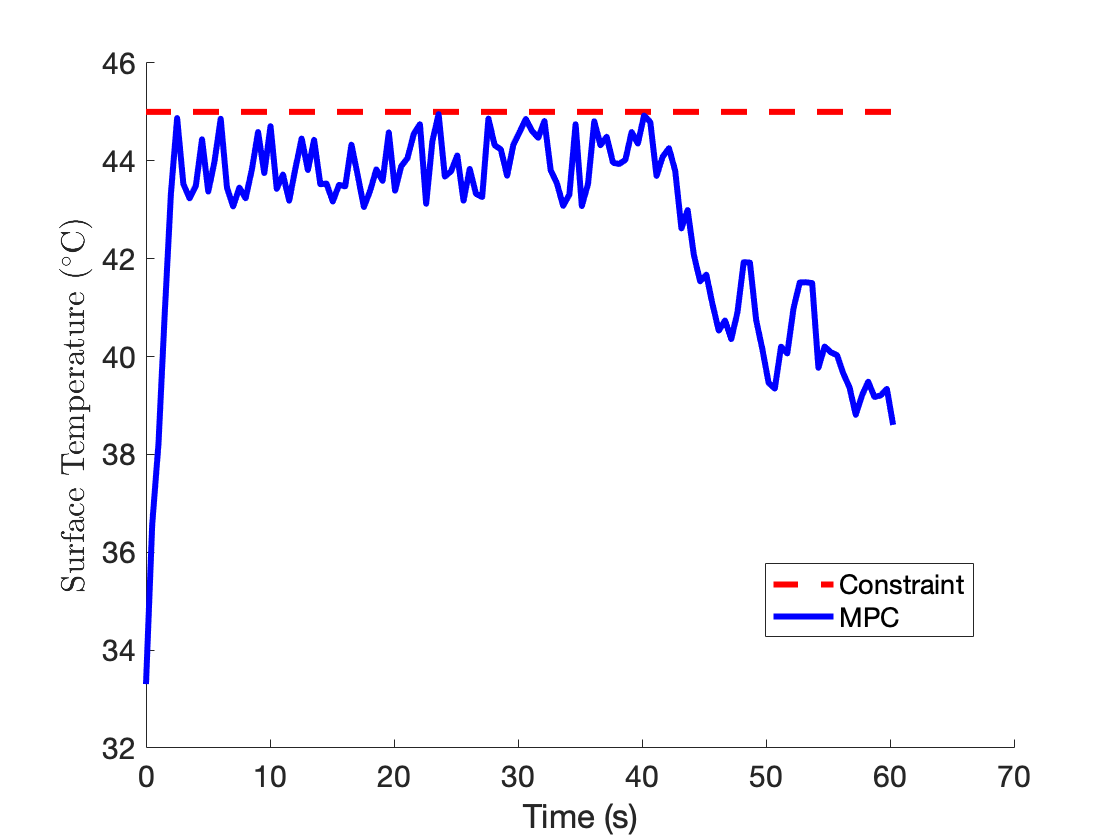


figure()
subplot(111)
hold on
T_max = (prob_info.x_max(1)+prob_info.xss(1))*ones(sum(mask),1);
plot(t(mask), T_max, 'r--', 'LineWidth', line_width, 'DisplayName', 'Constraint')
plot(t(mask), Tplot, 'b-', 'LineWidth', line_width, 'DisplayName', 'MPC')
xlabel('Time (s)')
ylabel('Surface Temperature ($^\circ$C)', 'Interpreter', 'latex')
legend('location', 'best')
set(gca, 'Fontsize', font_size)

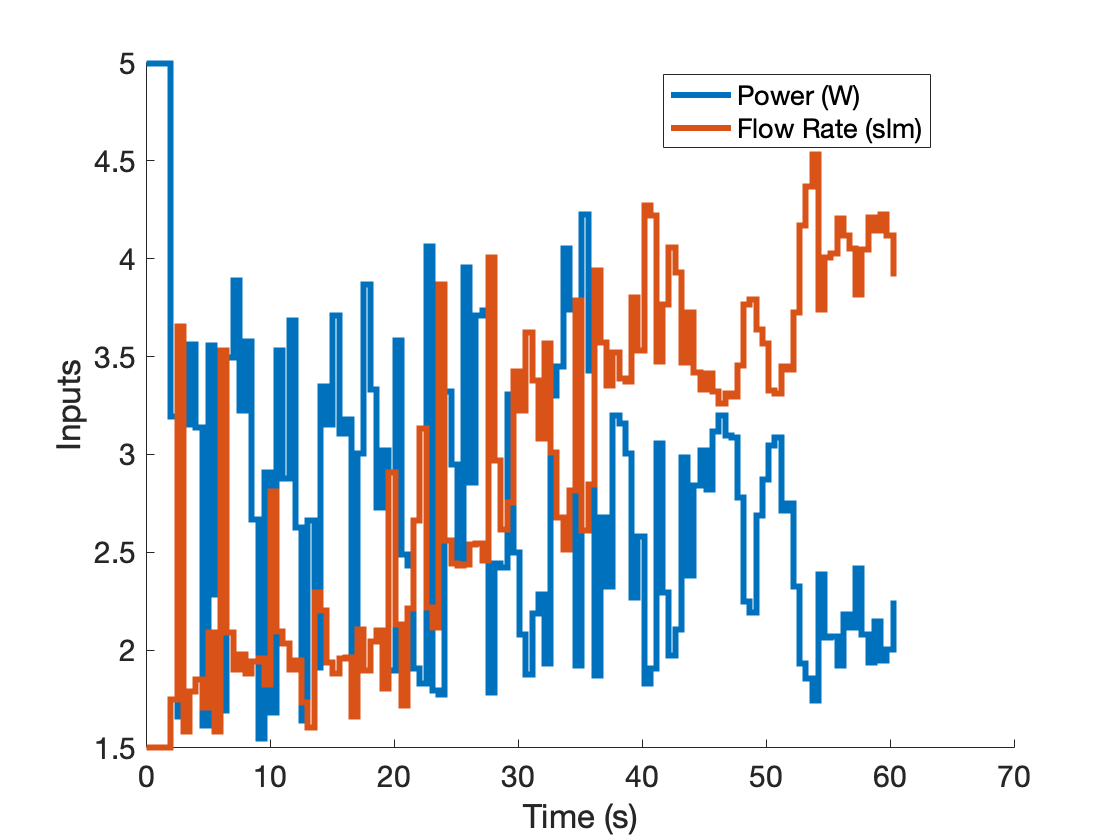


labels = {'Power (W)', 'Flow Rate (slm)'};
figure()
subplot(111)
hold on
for i = 1:prob_info.nu
    u_plot = sim_data.Usim(i,:)+prob_info.ussp(i);
    stairs(t(mask), u_plot(mask), 'LineWidth', line_width, 'DisplayName', labels{i})
end
xlabel('Time (s)')
ylabel('Inputs')
legend('location', 'best')
set(gca, 'Fontsize', font_size)

## save data

if ~isempty(save_file)
    save(save_file, 'sim_data', 'prob_info')
end

## remove package paths

rmpath(genpath('./config'), genpath('./utils'))